# Carga Nuevos Datos UGRID


close all
clear
clc

filename = 'Washington-1m-2008-09_UGRID.nc';

ncdisp(filename)

Source:
           C:\Users\segu2\OneDrive - Universidad Complutense de Madrid (UCM)\ProyBloomIoT\NuevoEEMS\Washington-1m-2008-09_UGRID.nc
Format:
           netcdf4
Global Attributes:
           Conventions = 'CF-1.4'
           Project     = 'EFDC_'
           utm_zone    = 'UTM Zone  10 Northern Hemisphere'
Dimensions:
           TIME  = 721   (UNLIMITED)
           NODE  = 1448
           CELL  = 1183
           FOUR  = 4
           LCM   = 1185
           IC    = 62
           JC    = 78
           KC    = 55
           KB    = 0     (UNLIMITED)
           NDYE  = 1
           NTOX  = 0     (UNLIMITED)
           NSED  = 0     (UNLIMITED)
           NSND  = 0     (UNLIMITED)
           NSXD  = 0     (UNLIMITED)
           NALG  = 2
           NZOO  = 0     (UNLIMITED)
           NSHF  = 0     (UNLIMITED)
           NQCTL = 0     (UNLIMITED)
           NQWR  = 0     (UNLIMITED)
           NPD   = 0     (UNLIMITED)
Variables:
    mesh           
           Size:       1x1
          

ncinfo = ncinfo(filename);

% Indices
tau = 100; % Time index
lyr = 55;  % Layer (top is 55) 
IJ = 798;  % Cell number (near lake center)
IJ = 445;  % Cell number (near outlet center)

% Read data
lonc = ncread(filename,'lonc');
latc = ncread(filename,'latc');
lon = ncread(filename,'lon');
lat = ncread(filename,'lat');
nv = ncread(filename,'nv');
sigma = ncread(filename,'sigma');
BELV = ncread(filename,'BELV');
WSEL = ncread(filename,'WSEL');
temp = ncread(filename,'temperature');
RSSBC = ncread(filename,'RSSBC');
CUV = ncread(filename,'CUV');
bottom_layer = ncread(filename,'bottom_layer');
ALG = ncread(filename,'ALG'); %Algas
time = ncread(filename,'time'); %Dias desde 20050101
wind_x=ncread(filename,'wind_x'); %Velocidad viento este (m/s)
wind_y=ncread(filename,'wind_y'); %Velocidad viento norte (m/s)
nox=ncread(filename,'NOX');       %Nitratos (mg/L)
nhx=ncread(filename,'NHX');       %Ammonia nitrogen (mg/L)
don=ncread(filename,'DON');       %Dissolved organic nitrogen (mg/L)
dop=ncread(filename,'DOP');       %Dissolved organic phosporo (mg/L)
saa=ncread(filename,'SAA');       %Available dissolved silica (mg/L)
dox=ncread(filename,'DOX');       %Oxigeno disuelto (mg/L)
u=ncread(filename,'U');           %Velocidad del agua este(m/s)
v=ncread(filename,'V');           %Velocidad del agua norte(m/s)
w=ncread(filename,'W');           %Velocidad del agua arriva(m/s)

%Otras variables
% float32 DON(TIME, KC, CELL), 
% float32 NHX(TIME, KC, CELL), 
% float32 NOX(TIME, KC, CELL), 
% float32 SUU(TIME, KC, CELL), 
% float32 SAA(TIME, KC, CELL), 
% float32 COD(TIME, KC, CELL), 
% float32 DOX(TIME, KC, CELL)


ncinfo.Variables(14).Attributes(3).Name

ans = 'units'

ncinfo.Variables(14).Attributes(3).Value

ans = 'days since 2005-01-01 00:00:00'

inidt=datetime(ncinfo.Variables(14).Attributes(3).Value(end-18:end))

inidt = datetime
   01-Jan-2005


dt=inidt+time*days(1)

dt = 721×1 datetime array
   23-Aug-2008 00:00:00
   23-Aug-2008 00:30:00
   23-Aug-2008 01:00:00
   23-Aug-2008 01:30:00
   23-Aug-2008 02:00:00
   23-Aug-2008 02:30:00
   23-Aug-2008 03:00:00
   23-Aug-2008 03:30:00
   23-Aug-2008 04:00:00
   23-Aug-2008 04:30:00
   23-Aug-2008 05:00:00
   23-Aug-2008 05:30:00
   23-Aug-2008 06:00:00
   23-Aug-2008 06:30:00
   23-Aug-2008 07:00:00
   23-Aug-2008 07:30:00
   23-Aug-2008 08:00:00
   23-Aug-2008 08:30:00
   23-Aug-2008 09:00:00
   23-Aug-2008 09:30:00
   23-Aug-2008 10:00:00
   23-Aug-2008 10:30:00
   23-Aug-2008 11:00:00
   23-Aug-2008 11:30:00
   23-Aug-2008 12:00:00
   23-Aug-2008 12:30:00
   23-Aug-2008 13:00:00
   23-Aug-2008 13:30:00
   23-Aug-2008 14:00:00
   23-Aug-2008 14:30:00


hours=hour(dt);
sun=max(cos((hours+12)/24*2*pi),0); %Genero el Sol Sintético

lonF = lon(nv);
latF = lat(nv);
sigma(sigma == 0) = NaN;
sumRSSBC = sum(RSSBC);
sumRSSBC(sumRSSBC==0) = [];

% Get z and depth
z = BELV(:,1)' + sigma.*(WSEL(:,tau)' - BELV(:,1)');
depth = WSEL(:,tau)' - z;


% figure(1); clf
% patch(lonF,latF,'w'); hold on
% plot(lon,lat,'r.')
% plot(lonc, latc, 'bo')
% xlabel('Longitude'); ylabel('Latitude'); title('Grid nodes')
% legend({'Grid','Vertex','Cell center'},'location','best')
% axis equal tight

% figure(1)
% lyr=55
% for tau=1:100:700
%     subplot(1,2,1)
%     quiver(lonc,latc,u(:,lyr,tau)/10,v(:,lyr,tau)/10,0);
%     title(['Mean Water Speed (m/s):',num2str(mean(sqrt(u(:,lyr,tau).^2+v(:,lyr,tau).^2),'omitnan'))])
%     
%     subplot(1,2,2)
%     quiver(lonc,latc,wind_x(:,tau)/1000,wind_y(:,tau)/1000,0);
%     title(['Mean Wind Speed (m/s):',num2str(mean(sqrt(wind_x(:,tau).^2+wind_y(:,tau).^2),'omitnan'))])
%     drawnow
%     pause(0.5)
% end

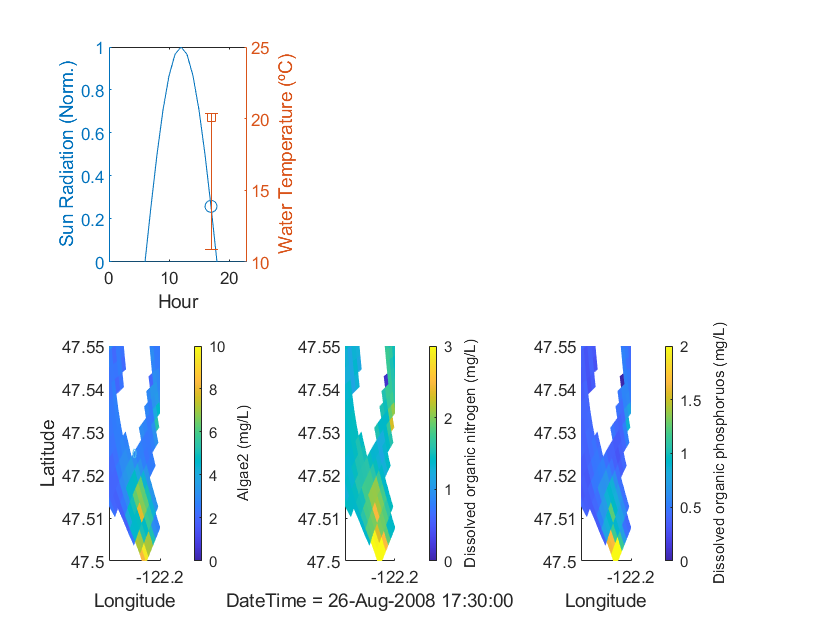

figure(3)
tau = 180; % Time index
lyr = 55;  % Layer (top is 55) 

subplot(2,3,1)
yyaxis left
plot(hours,sun,hours(tau),sun(tau),'o');
ylabel('Sun Radiation (Norm.)')
yyaxis right
me=mean(Temp(:,lyr,tau),'omitnan');
ma=max(Temp(:,lyr,tau))-me;
mi=me-min(temp(:,lyr,tau));
errorbar(hours(tau),me,mi,ma,'s');
ylabel('Water Temperature (ºC)')
xlabel('Hour')
%nhx=ncread(filename,'NHX');       %Ammonia nitrogen (mg/L)
%don=ncread(filename,'DON');       %Dissolved organic nitrogen (mg/L)
%saa=ncread(filename,'SAA');       %Available dissolved silica (mg/L)



subplot(2,3,4);
colormap('default')
c1=colorbar;
%caxis([0 0.5]);
caxis([0 10]);
xlabel('Longitude'); 
ylabel('Latitude'); 
%c1.Label.String = 'Ammonia nitrogen(mg/L)';
c1.Label.String = 'Algae2 (mg/L)';
myxlim=[-122.25,-122.2];
myylim=[47.5,47.55];
xlim(myxlim);
ylim(myylim);
%patch(lonF,latF,nhx(:,lyr,tau),'EdgeColor','none'); % Two types of algae
patch(lonF,latF,ALG(:,lyr,2,tau),'EdgeColor','none'); % Two types of algae
[lat,lon] = scircle1(mean(myylim),mean(myxlim),0.001);
hold on;
plot(lon,lat,'r')

subplot(2,3,5)
colormap('default')
c2=colorbar;
c2.Label.String = 'Dissolved organic nitrogen (mg/L)';
caxis([0 3]);
%xlabel('Longitude'); 
 xlabel(['DateTime = ', datestr(dt(tau))])
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)
patch(lonF,latF,don(:,lyr,tau),'EdgeColor','none'); % Two types of algae

subplot(2,3,6)
colormap('default')
c3=colorbar;
c3.Label.String = 'Dissolved organic phosphoruos (mg/L)';
caxis([0 2]);
xlabel('Longitude'); 
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)
patch(lonF,latF,dop(:,lyr,tau),'EdgeColor','none'); % Two types of algae

## Simula

close all;
clf;
% % Open video file
%      vid = VideoWriter('video','MPEG-4');
%      vid.Quality = 100;
%      open(vid);


f=figure(2);
f.Position(3:4) = [1000 500];
myxlim=[-122.25,-122.2];
myylim=[47.5,47.55];

subplot(2,3,1);
colormap('default')
xlim([0,24])
ylim([0,1])

subplot(2,3,2)
xlim(myxlim)
ylim(myylim)
title('Water Speed (m/s)')

subplot(2,3,3)
xlim(myxlim)
ylim(myylim)
title('Wind (m/s)')

subplot(2,3,4);
colormap('default')
c1=colorbar;
caxis([0 10]);
xlabel('Longitude'); 
ylabel('Latitude'); 
c1.Label.String = 'Algae2 (mg/L)';
xlim(myxlim)
ylim(myylim)

subplot(2,3,5)
colormap('default')
c2=colorbar;
c2.Label.String = 'Disolved Oxigen (mg/L)';
caxis([0 25]);
xlabel('Longitude'); 
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)

subplot(2,3,6)
colormap('default')
c3=colorbar;
c3.Label.String = 'Nitrate (mg/L)';
caxis([0 0.5]);
xlabel('Longitude'); 
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)

for lyr = 55 %1:55
 for tau = 1:1:length(time)
    subplot(2,3,1)
    yyaxis left
    plot(hours,sun,hours(tau),sun(tau),'o');
    ylabel('Sun Radiation (Norm.)')
    ylim([0,1])
    yyaxis right
    me=mean(temp(:,lyr,tau),'omitnan');
    ma=max(temp(:,lyr,tau))-me;
    mi=me-min(temp(:,lyr,tau));
    %errorbar(hours(tau),me,mi,ma,'s');
    errorbar(hours(tau),me,ma,'s');
    ylabel('Water Temperature (ºC)')
    xlabel('Hour')
    ylim([19,21])
    subplot(2,3,2)
    %patch(lonF,latF,Temp(:,lyr,tau),'EdgeColor','none');
    quiver(lonc,latc,u(:,lyr,tau)/10,v(:,lyr,tau)/10,0);
    xlim(myxlim)
    ylim(myylim)
    title(['Mean Water Speed (m/s):',num2str(mean(sqrt(u(:,lyr,tau).^2+v(:,lyr,tau).^2),'omitnan'))])
    subplot(2,3,3)
    quiver(lonc,latc,wind_x(:,tau)/1000,wind_y(:,tau)/1000,0);
    xlim(myxlim)
    ylim(myylim)
    title(['Mean Wind Speed (m/s):',num2str(mean(sqrt(wind_x(:,tau).^2+wind_y(:,tau).^2)))])
    subplot(2,3,4)
    patch(lonF,latF,ALG(:,lyr,2,tau),'EdgeColor','none'); % Two types of algae
    subplot(2,3,5)
    patch(lonF,latF,dox(:,lyr,tau),'EdgeColor','none'); % Two types of algae
    xlabel(['DateTime = ', datestr(dt(tau))])
    subplot(2,3,6)
    patch(lonF,latF,nox(:,lyr,tau),'EdgeColor','none'); % Two types of algae
    drawnow
    
    % % Record video
    %      frame = getframe(gcf);
    %      writeVideo(vid,frame);
    
    %figure(3)
    %plot(Temp(IJ,:,tau), z(:,IJ)); xlim([18:21])
    %plot(ALG(IJ,:,2,tau), -depth(:,IJ)); xlim([0,5])
    %drawnow

 end
end
% % Close video file
%     close(vid);

Simulacion Parcial


close all;
clf;

%Intial State of Bloom
tau=100;
lyr=55;
seccion=1:200;
map = [lonc(seccion),latc(seccion)];
ip=10

ip = 10

%ip=2
x0=[0,lonc(ip),latc(ip)]

x0 = 1×3 single row vector
         0 -122.2169   47.5065


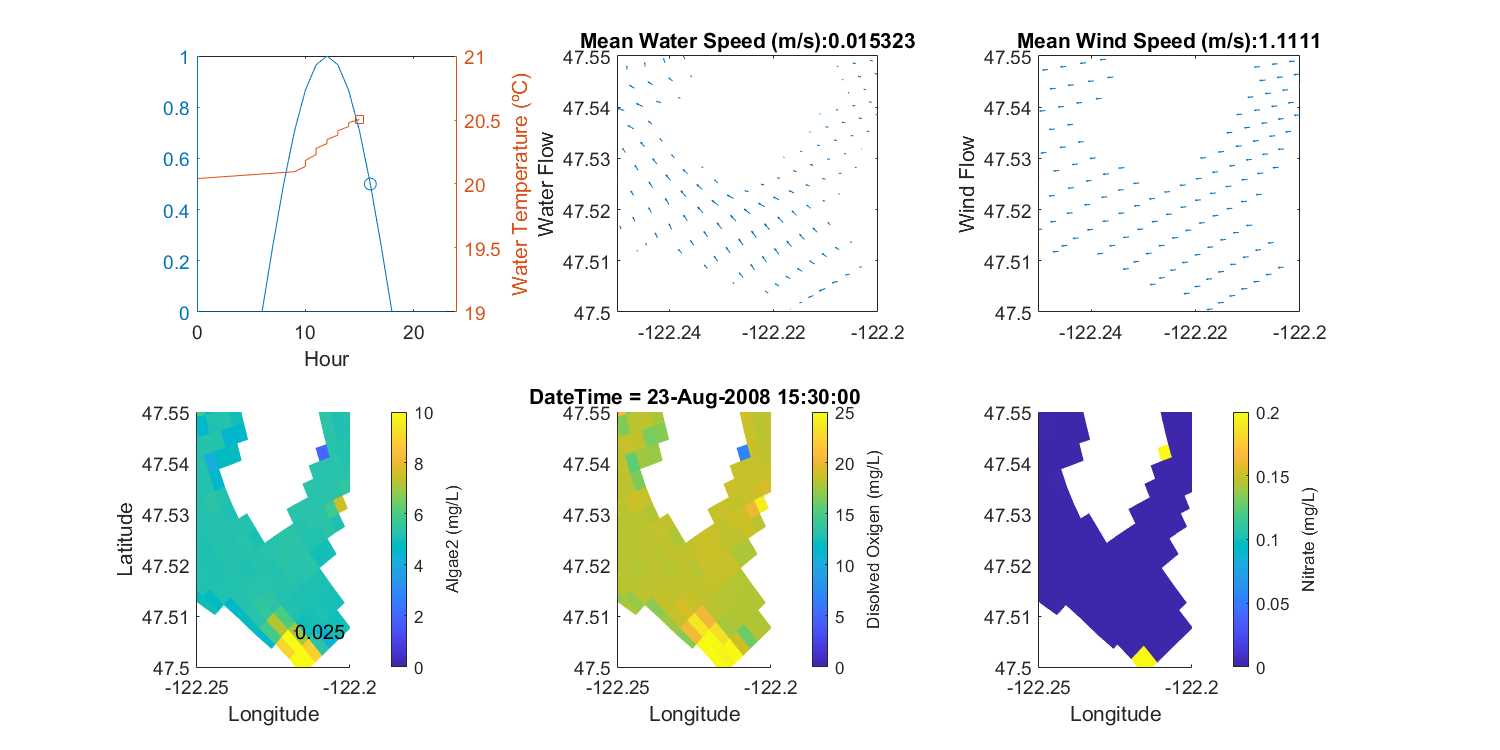

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in ylabel (line 65)
    h = get(ax,'YLabel');

%x=[1,-122.215,45.501]
x=x0;
f=figure(2);
f.Position(3:4) = [1000 500];
myxlim=[-122.25,-122.2];
myylim=[47.5,47.55];


subplot(2,3,1);
colormap('default')

xlim([0,24])
ylim([0,1])

subplot(2,3,2)
 
xlim(myxlim)
ylim(myylim)
title('Water Speed (m/s)')

subplot(2,3,3)

xlim(myxlim)
ylim(myylim)
title('Wind (m/s)')

subplot(2,3,4);
colormap('default')
c1=colorbar;
caxis([0 10]);
xlabel('Longitude'); 
ylabel('Latitude'); 
c1.Label.String = 'Algae2 (mg/L)';
xlim(myxlim)
ylim(myylim)


subplot(2,3,5)
colormap('default')
c2=colorbar;
c2.Label.String = 'Disolved Oxigen (mg/L)';
caxis([0 25]);
xlabel('Longitude'); 
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)

subplot(2,3,6)
colormap('default')
c3=colorbar;
c3.Label.String = 'Nitrate (mg/L)';
caxis([0 0.2]);
%c3.Label.String = 'Dissolved organic nitrogen (mg/L)';
%caxis([0 5]);
xlabel('Longitude'); 
%ylabel('Latitude'); 
xlim(myxlim)
ylim(myylim)

vtemp=mean(temp(:,lyr,tau),'omitnan');;
vhour=0;
for lyr = 55 %1:55
 for tau = 20:1:length(time)
 %for tau = 100:1:300 
    subplot(2,3,1)
     yyaxis left
     plot(hours,sun,hours(tau),sun(tau),'o');
     ylabel('Sun Radiation (Norm.)')
     ylim([0,1])
     yyaxis right
     me=mean(temp(:,lyr,tau),'omitnan');
     ma=max(temp(:,lyr,tau))-me;
     mi=me-min(temp(:,lyr,tau));
     %plot(vhour,vtemp);hold on;
     plot(vhour,vtemp,'-',vhour(end),vtemp(end),'s');
     %errorbar(hours(tau),vtemp(end),ma,'s'); 
     ylabel('Water Temperature (ºC)')
     xlabel('Hour')
     ylim([19,21])
    subplot(2,3,2)
     quiver(lonc,latc,u(:,lyr,tau)/10,v(:,lyr,tau)/10,0);
     xlim(myxlim)
     ylim(myylim)
     title(['Mean Water Speed (m/s):',num2str(mean(sqrt(u(:,lyr,tau).^2+v(:,lyr,tau).^2),'omitnan'))])    
     ylabel('Water Flow')
    subplot(2,3,3)
     quiver(lonc,latc,wind_x(:,tau)/1000,wind_y(:,tau)/1000,0);
     xlim(myxlim)
     ylim(myylim)
     title(['Mean Wind Speed (m/s):',num2str(mean(sqrt(wind_x(:,tau).^2+wind_y(:,tau).^2)))])
     ylabel('Wind Flow')
    subplot(2,3,4)
     cla
     patch(lonF,latF,ALG(:,lyr,2,tau),'EdgeColor','none'); % Two types of algae
     hold on;
     bt=text(x(2),x(3),num2str(x(1),2));
     [lat,lon] = scircle1(x(3),x(2),0.001*sqrt(x(1)));
     plot(lon,lat,'r')
     hold off;
    subplot(2,3,5)
     patch(lonF,latF,dox(:,lyr,tau),'EdgeColor','none'); % Two types of algae
     title(['DateTime = ', datestr(dt(tau))])
    subplot(2,3,6)
     patch(lonF,latF,nox(:,lyr,tau),'EdgeColor','none'); % Two types of algae
     %patch(lonF,latF,don(:,lyr,tau),'EdgeColor','none'); % Two types of algae
   
    %Initial Bloom
     if (hours(tau)==0) 
         x=x0;
         bloom=false;
         vtemp=[];
         vhour=[];
     end
    %Input of Bloom Model 
     [ip,dist] = dsearchn(map,[x(2),x(3)]);
         
     %ux(1)=nox(ip,lyr,tau)/0.3*dox(ip,lyr,tau)/50+nox(ip,lyr,tau)/0.3*sun(tau);
     %ux(1)=nox(ip,lyr,tau)/0.5*dox(ip,lyr,tau)/20*sun(tau);
     %ux(1)=nox(ip,lyr,tau)/10;
     
     %breath=don(ip,lyr,tau)*dox(ip,lyr,tau);%nox
     %photosynthesis=don(ip,lyr,tau)*sun(tau);%nox
     breath=nox(ip,lyr,tau)*dox(ip,lyr,tau);%nox
     photosynthesis=nox(ip,lyr,tau)*sun(tau);%nox
     kbreath=0.05;%3/50;
     kphoto=5;%3;
     ux(1)=kbreath*breath+kphoto*photosynthesis;
     ux(2)=u(ip,lyr,tau);
     ux(3)=v(ip,lyr,tau);
    %Logic of Bloom
     bloom=bloomlog(dox(ip,lyr,tau),bloom);   
    %Dynamic of Bloom
     if bloom  
         xdel=bloomdyn(x,ux);
     else      
         x=x0;xdel=[0,0,0];
     end
    %Restrictions
    
    %Update of Bloom
     x=x+xdel;
     
    %Prepara vector Temperaturas
     vhour=[vhour,hours(tau)];
     vtemp=[vtemp,temp(ip,lyr,tau)];
    drawnow
    
 end
end

Dinámica my simplificada del Bloom

function xdel=bloomdyn(x,u)
%This function implements a simplyfied dynamic if the bloom
%x(0)=size,x(1)=lat,x(2)=lon
%u(1)=Nfood,u(2)=eastwaterspeed,u(3)=nordwaterspeed
 kdecline=1/6;
 kgrow=1;
 xdel(1)=kgrow*u(1)-kdecline*x(1);
 k2d=1/60;
 xdel(2)=k2d*u(2);
 xdel(3)=k2d*u(3);
end

function bloom=bloomlog(dox,bloom)
%Is It a Bloom? At actual position.
%Rich in oxigen=>It is a bloom
%Poor in oxigen=>It is not a bloom
%Other case bypass bloom
 if (dox>20), bloom=true;
 elseif (dox<15), bloom=false;
 end
end